## 导入并预处理数据

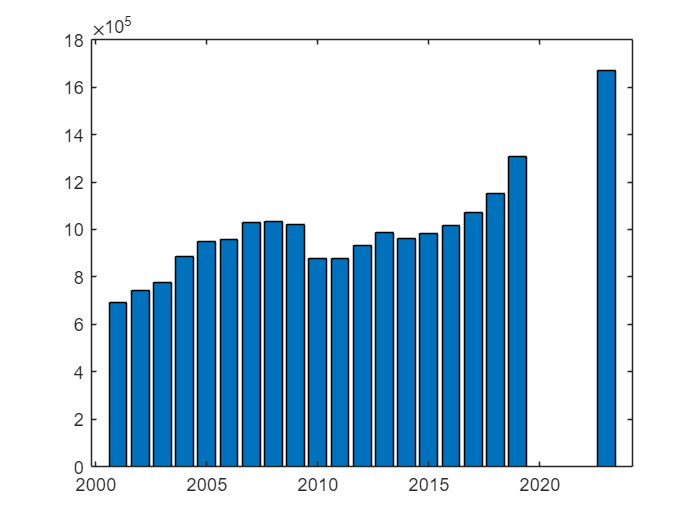

clear, clc;
data=load("data.mat");  %导入人数
data=table2array(data.data);
data(20,2)=NaN;  data(21,2)=NaN;  data(22,2)=NaN;
bar(data(:,1),data(:,2));

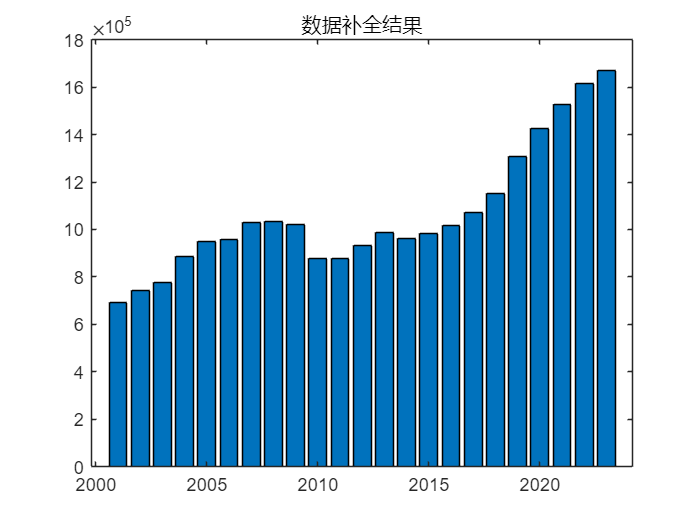

% 1.线性插值 linear 2.分段三次样条插值 spline 3.保形分段三次样条插值 pchip 4.移动滑窗插补 movmean
chazhi_fa = char('linear', 'spline', 'pchip', 'movmean');
choice_2 = 3;
if choice_2 ~= 4
    data = fillmissing(data,strtrim(chazhi_fa(choice_2,:))); % strtrim 是为了去除字符串组的空格
else
    data = fillmissing(data,'movmean',10); % 窗口长度为 10 的移动均值
end
bar(data(:,1),data(:,2));
title('数据补全结果');

ADF检验结果:
是否拒绝原假设（序列非平稳）: 0
p值: 0.9990
KPSS检验结果:
是否拒绝原假设（序列平稳）: 0
p值: 0.0100


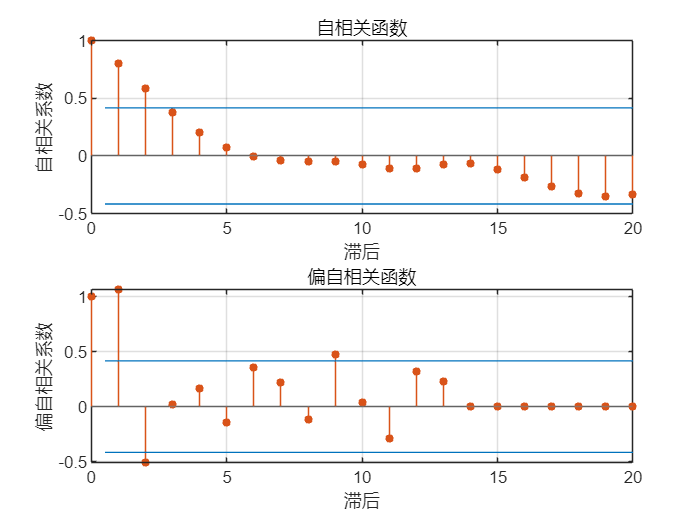

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant         23558         25963           0.9074     0.3642
    AR{1}         -0.14644       0.78973         -0.18543    0.85289
    AR{2}          0.52688       0.36695           1.4358    0.15105
    MA{1}          0.68318       0.73633          0.92781     0.3535
    Variance    3.5302e+09       0.22928       1.5397e+10          0




% 时间序列预测测试
y=data(:,2); PreTime=20;
forecastTest=ARIMA(PreTime,y);

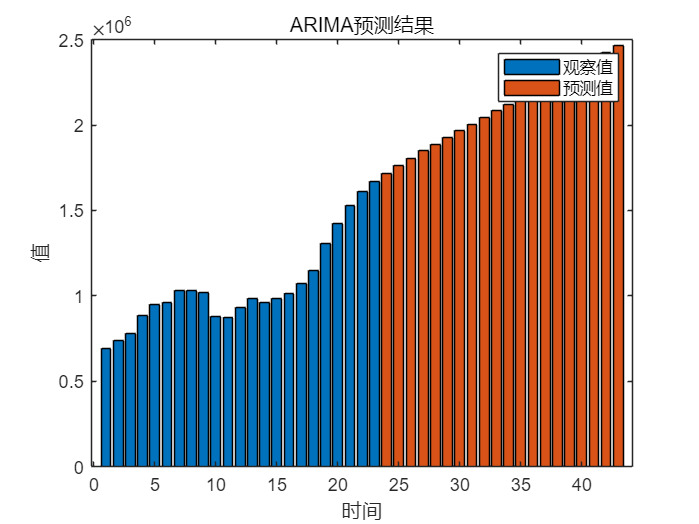

figure;  bar(y);  hold on;
time_axis = (length(y)+1:length(y)+PreTime)';
bar(time_axis, forecastTest);
xlabel('时间');  ylabel('值');
legend('观察值', '预测值');  title('ARIMA预测结果');

## 目标函数（1）maxR s.t. Nmax>0, 0<=alpha_1(t)+alpha_2(t)<=alpha_max

function R=Revenue1(Nmax,alpha_1,alpha_2,PreTime)  %alpha1为碳alpha2为基础
    %参数
    P0=1;  N0=1;  S0=0;  Ep=1;
    Cmean=14.4;  Imean=1;  I0=10;
    r1=1/pi;  r2=1;  k1=1;  k2=1;
    lambda=[0.4;0.3;0.3];  %可持续性因子权重

    N=zeros(PreTime,1);  Rt=zeros(PreTime,1);
    S=zeros(PreTime,1);  I=zeros(PreTime,1);

    N(1)=N0*(1+alpha_1(1)+alpha_2(1))^Ep;
    N(1)=max([Nmax,r1*N(1)*atan(r2*S0)]);
    Rt(1)=P0*N(1);  

    %可持续性因子，未作单位化处理; Satis为满意度函数，Rt为收入，N为人数
    I(1)=I0+k2*alpha_2(1)*P0*N(1);
    S(1)=[-Cmean*N(1),-Imean*N(1)/I0,Satis(Rt(1),N(1))]*lambda;
    for t=2:PreTime
        N(t)=N(t-1)*((1+alpha_1(t)+alpha_2(t))/(1+alpha_1(t-1)+alpha_2(t-1)))^Ep;
        N(t)=max([Nmax,r1*N(t)*atan(r2*S(t-1))]);
        Rt(t)=P0*N(t);  
        C=Cmean*N(t)-k1*alpha_1(t)*P0*N(t);
        I(t)=I(t-1)+k2*alpha_2(t)*P0*N(t);
        S(t)=[-C,Imean*N(t)/I(t-1),Satis(Rt(t),N(t))]*lambda;
    end
    R=sum(Rt);
end

## 目标函数（2）maxR s.t. Nmax>0, 0<=alpha_1(t)+alpha_2(t)<=alpha_max

function R=Revenue2(Nmax,alpha_1,alpha_2,PreTime,N0)
    %参数,统一使用列向量
    P0=1;  S0=0;  Ep=1;
    Cmean=14.4;  Imean=1;  I0=10;
    r1=1/pi;  r2=1;  k1=1;  k2=1;
    lambda=[0.4;0.3;0.3];  %可持续性因子权重

    N=zeros(PreTime,1);  Rt=zeros(PreTime,1);
    S=zeros(PreTime,1);  I=zeros(PreTime,1);

    %时间序列预测
    N(1)=ARIMA(1,N0);    %ARIMA为时间序列预测
    N(1)=N(1)*(1+alpha_1(1)+alpha_2(1))^Ep;
    N(1)=max([Nmax,r1*N(1)*atan(r2*S0)]);
    Rt(1)=P0*N(1);

    %可持续性因子，未作单位化处理; Satis为满意度函数，Rt为收入，N为人数
    I(1)=I0+k2*alpha_2(1)*P0*N(1);
    S(1)=[-Cmean*N(1),-Imean*N(1)/I0,Satis(Rt(1),N(1))]*lambda;
    N0=[N0;N(1)];
    for t=2:PreTime
        N(t)=ARIMA(1,N0);
        N(t)=N0(end)*(1+alpha_1(t)+alpha_2(t))^Ep;
        N(t)=max([Nmax,r1*N(t)*atan(r2*S(t-1))]);
        Rt(t)=P0*N(t);
        C=Cmean*N(t)-k1*alpha_1(t)*P0*N(t);
        I(t)=I(t-1)+k2*alpha_2(t)*P0*N(t);
        S(t)=[-C,Imean*N(t)/I(t-1),Satis(Rt(t),N(t))]*lambda;
    end
    R=sum(Rt);
end

## ARIMA算法

function forecastTest=ARIMA(PreTime,y)

% 拆分数据集为训练集和测试集
train_size = floor(0.8 * length(y));
train_data = y;

% 平稳性检验 - ADF检验
[h_adf, p_adf] = adftest(y);
fprintf('ADF检验结果:\n');
fprintf('是否拒绝原假设（序列非平稳）: %d\n', h_adf);
fprintf('p值: %.4f\n', p_adf);
 
% 平稳性检验 - KPSS检验
[h_kpss, p_kpss] = kpsstest(y);
fprintf('KPSS检验结果:\n');
fprintf('是否拒绝原假设（序列平稳）: %d\n', ~h_kpss);
fprintf('p值: %.4f\n', p_kpss);
 
% 确定参数
y_diff = train_data;
figure;
subplot(2,1,1);  autocorr(y_diff);
title('自相关函数');  xlabel('滞后');  ylabel('自相关系数');
subplot(2,1,2);  parcorr(y_diff);
title('偏自相关函数');  xlabel('滞后');  ylabel('偏自相关系数');
 
% 训练ARIMA模型
model = arima(2, 1, 1);
model = estimate(model, y_diff);
 
% 测试未来时间预测情况
horizon = PreTime;
[forecastTest, YMSE, forecastCI] = forecast(model, horizon, 'Y0', y_diff);
%ResultScale(:, 1) = forecastTest - 1.64*sqrt(YMSE); % 90%置信区间下限
%ResultScale(:, 2) = forecastTest + 1.64*sqrt(YMSE); % 90%置信区间上限
end